Anant Mital 

Student # 272484

## Problem 5

ff = @(x1,x2) -cos(x1).*cos(x2).*exp(-((x1-pi).^2+(x2-pi).^2));
% initial guess (0,0)
[xmin2, fmin2, flag, output] = fminsearch(@(x)ff(x(1), x(2)), [0;0])

xmin2 =     3.1416
    3.1416


fmin2 = -1.0000

flag = 1

output = struct with fields:
    iterations: 64
     funcCount: 111
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


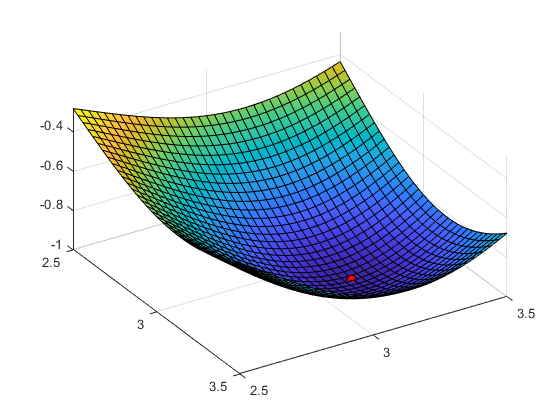


% initial guess (1,-1)
%[xmin2, fmin2, flag, output] = fminsearch(ff, [1;-1]);
% initial guess (4,1)
%[xmin2, fmin2, flag, output] = fminsearch(ff, [4;1]);

clf;
fsurf(ff, [2.5 3.5]);
view(58, 46);
hold on
plot3(xmin2(1), xmin2(2), fmin2, 'o', 'MarkerFaceColor', 'r',...
	'MarkerSize', 7, 'MarkerEdgeColor', 'black');
hold off

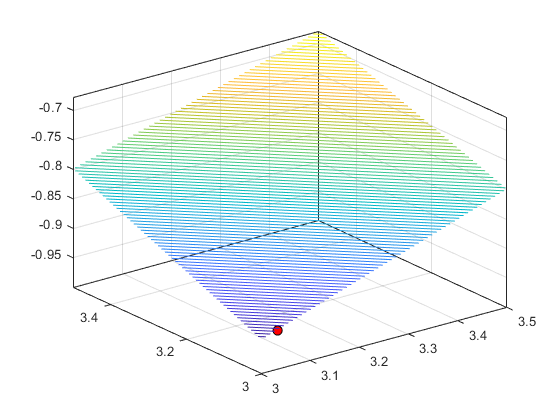

[X1, X2] = meshgrid([3 3.5]);
F = ff(X1, X2);
contour3(X1, X2, F, 100);
hold on
plot3(xmin2(1), xmin2(2), fmin2, 'o', 'MarkerFaceColor', 'r',...
	'MarkerSize', 7, 'MarkerEdgeColor', 'black')
hold off